# A first inside in trajectories

clear
mdl_twolink
twolink.plot(qz)
twolink.links(1, 2).a=0.6

 
twolink = 
 
two link:: 2 axis, RR, stdDH, slowRNE                            
 - from Spong, Hutchinson, Vidyasagar;                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|        0.6|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0, 0, 0), RPY/xyz = (0, 0, 90) deg                 
 


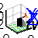

twolink.plot(qz,'zoom',1.5)

## Start and end points

P1=[1.5 0 0.3]

P1 =     1.5000         0    0.3000


P2=[0 0 0.3]

P2 =          0         0    0.3000


T1=transl(P1)

T1 =     1.0000         0         0    1.5000
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


T2=transl(P2)

T2 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


## Chosing the ikine solution 

Elbow Up

qu=twolink.ikine(T1,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

qu =     0.4257   -0.6152


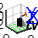

twolink.plot(qu,'zoom',2)

## Trajectory

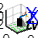

hold on
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])

Xs=linspace(P1(1),P2(1),20)

Xs =     1.5000    1.4211    1.3421    1.2632    1.1842    1.1053    1.0263    0.9474    0.8684    0.7895    0.7105    0.6316    0.5526    0.4737    0.3947    0.3158    0.2368    0.1579    0.0789         0


Ys=linspace(P1(2),P2(2),20)

Ys =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Zs=linspace(P1(3),P2(3),20)

Zs =     0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000    0.3000


Traject=transl([Xs' Ys' Zs'])

Traject = Traject(:,:,1) =

    1.0000         0         0    1.5000
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


Traject(:,:,2) =

    1.0000         0         0    1.4211
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


Traject(:,:,3) =

    1.0000         0         0    1.3421
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


Traject(:,:,4) =

    1.0000         0         0    1.2632
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


Traject(:,:,5) =

    1.0000         0         0    1.1842
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


Traject(:,:,6) =

    1.0000         0         0    1.1053
         0 

## ikine and Plotting 

### Joint space

ikine till :16

qs_u=twolink.ikine(Traject(:,:,1:16),'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

qs_u =     0.4257   -0.6152
    0.5366   -0.8963
    0.6219   -1.1122
    0.6941   -1.2960
    0.7581   -1.4603
    0.8160   -1.6111
    0.8690   -1.7524
    0.9180   -1.8864
    0.9632   -2.0151
    1.0047   -2.1400


### Plotting

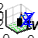

twolink.plot(qs_u, 'zoom',2)

## Debbuging singularities

Testing 16's trajectory point

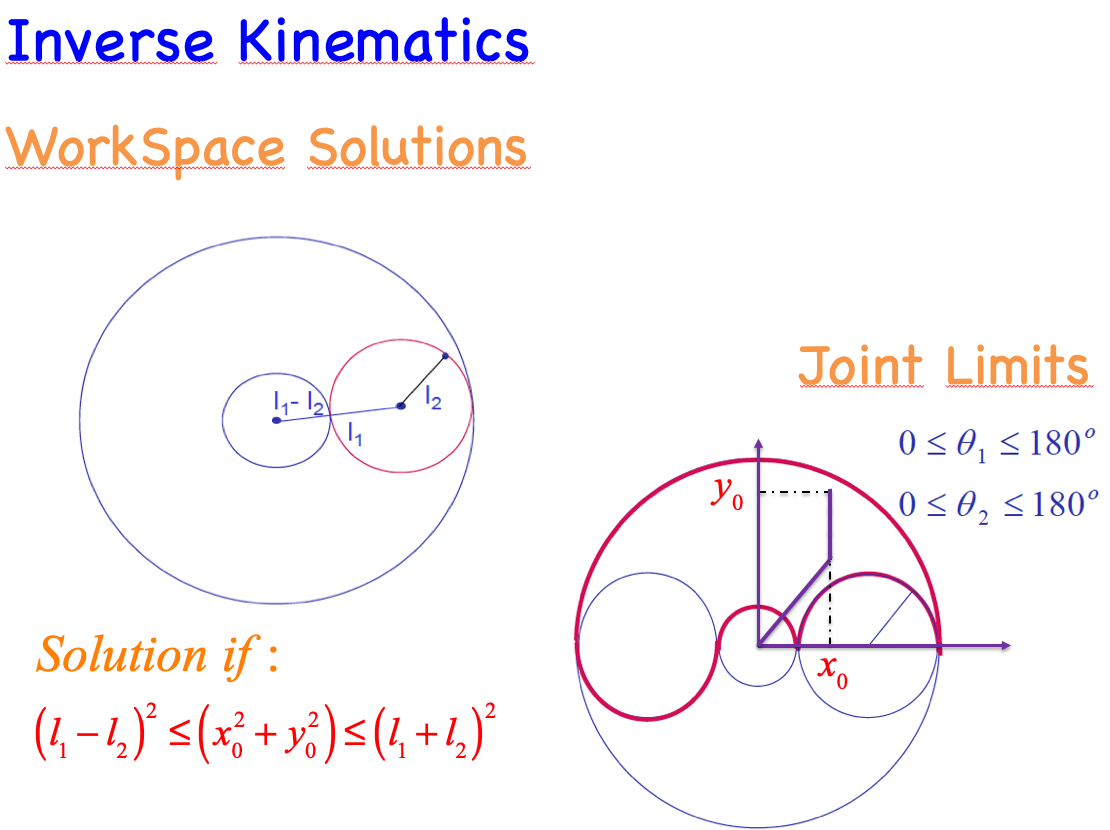

P16=transl(Traject(:,:,16))

P16 =     0.3158
         0
    0.3000


xoyo=(P16(1)^2+P16(3)^2)

xoyo = 0.1897

L1=twolink.links(1, 1).a

L1 = 1

L2=twolink.links(1, 2).a

L2 = 0.6000

L1min2=(L1-L2)^2

L1min2 = 0.1600

L1plus2=(L1+L2)^2

L1plus2 = 2.5600

Testing 17's trajectory point

P17=transl(Traject(:,:,17))

P17 =     0.2368
         0
    0.3000


xoyo=(P17(1)^2+P17(3)^2)

xoyo = 0.1461

L1=twolink.links(1, 1).a

L1 = 1

L2=twolink.links(1, 2).a

L2 = 0.6000

L1menos2=(L1-L2)^2

L1menos2 = 0.1600

L1mas2=(L1+L2)^2

L1mas2 = 2.5600

## Solution: From below

P1=[1.5 0 0.5]

P1 =     1.5000         0    0.5000


P2=[-1.5 0 0.5]

P2 =    -1.5000         0    0.5000


T1=transl(P1)

T1 =     1.0000         0         0    1.5000
         0    1.0000         0         0
         0         0    1.0000    0.5000
         0         0         0    1.0000


T2=transl(P2)

T2 =     1.0000         0         0   -1.5000
         0    1.0000         0         0
         0         0    1.0000    0.5000
         0         0         0    1.0000


qd=twolink.ikine(T1,'mask',[1 1 0 0 0 0 ], 'q0',[-pi/4 0])

qd =     0.2030    0.3176


twolink.plot(qd,'zoom',2)
hold on
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
ts=0.05

ts = 0.0500

tf=2

tf = 2

t=(0:ts:tf)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


[S SD SDD]=tpoly(0,1,t,0,0)

S =          0
    0.0002
    0.0012
    0.0038
    0.0086
    0.0161
    0.0266
    0.0405
    0.0579
    0.0789


SD =          0
    0.0089
    0.0338
    0.0722
    0.1215
    0.1794
    0.2438
    0.3127
    0.3840
    0.4561


SDD =          0
    0.3473
    0.6412
    0.8845
    1.0800
    1.2305
    1.3387
    1.4077
    1.4400
    1.4386


Trajec=ctraj(T1,T2,S);
qs_d=twolink.ikine(Trajec,'mask',[1 1 0 0 0 0 ], 'q0',[pi/2 0])

qs_d =     0.4405   -0.3176
    0.4419   -0.3212
    0.4511   -0.3443
    0.4726   -0.3978
    0.5064   -0.4814
    0.5505   -0.5889
    0.6026   -0.7140
    0.6610   -0.8520
    0.7246   -0.9995
    0.7926   -1.1540


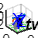

twolink.plot(qs_d, 'zoom',2)

## Visualizing trajectory data

### Derivatives

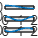

figure
traj_points_xyz=transl(Trajec);
velocity=diff(traj_points_xyz(:,1));
accel=diff(velocity);
subplot(3,1,1)
plot(t,traj_points_xyz(:,1))
title('Task domain','FontAngle','italic','FontSize',26);
ylabel('$x [m]$','FontSize',26,'Interpreter','latex');
xlabel('Time [s]','FontSize',18);
grid on
subplot(3,1,2)
plot((0:ts:tf-ts),velocity)
xlabel('Time [s]','FontSize',18);
ylabel('$\dot x\;[m/s]$','FontSize',26,'Interpreter','latex');
grid on
subplot(3,1,3)
plot((0:ts:tf-2*ts),accel)
xlabel('Time [s]','FontSize',18);
ylabel('$\ddot x\;[m/{s^2}]$','FontSize',26,'Interpreter','latex');
grid on

### Task - space 

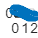

figure
scatter(t,traj_points_xyz(:,1))
grid on

### 3D trajectory

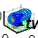

figure
axis([-2 2 -2 2 -1.5 1.5])
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
hold on
scatter3(traj_points_xyz(:,1),traj_points_xyz(:,2),traj_points_xyz(:,3))
twolink.plot(qs_d, 'zoom',2, 'workspace',[-2 2 -2 2 -1.5 1.5] )